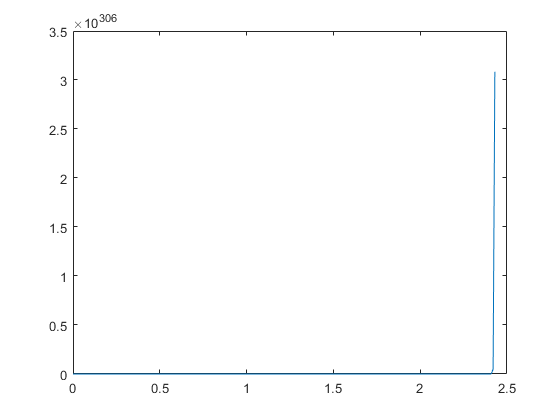

dT = 1e-2;
R = 8.3145;
Pstd = 101325;
nF = 2*96485;
C_act = 1;
A = 560;
Rohm = 0;
Ifc = 0;
E_act = [0];
E_act_d = 0;
T = 313;
Temp = 0;

while Ifc < 50
    Ifc = Ifc + dT;
    E_act = trapz([E_act(end) E_act_d]);
    J = Ifc/A;
    J0 = 45/A;
    Tc = T-273.15;
    
    PH2Osat = 10^(-2.18+2.95e-2*Tc-9.18e-5*Tc^2+1.44e-7*Tc^3);
    Pa = 1.45;
    Pc = 1;
    P_H2 = 0.5*PH2Osat*(exp(-(1.635*J/T^1.334))*(Pa/PH2Osat)-1);
    P_O2 = PH2Osat*(exp(-(4.192*J/T^1.334))*(Pc/PH2Osat)-1);
    
    E_Ner = 1.229 + (T-298.15) * (-0.85e-3) + T*R/nF * log(P_H2*P_O2^0.5);
    
    
    
    %% Ohmic loss
    %     E_ohm = - Ifc*(delta_m/((Water_content*5.139e-3-3.26e-3)*exp(1268*(1/303-1/T))));
    E_ohm = -Ifc * (1.605e-2-3.5e-5*T+8e-5*Ifc);
    
    
    %% Concentration loss
    %     E_con = 0.016*log(1-Ifc/40);
    E_con = R*T/nF*log(1-Ifc/40);
    %
    %     if T>= 312.15
    %         E_con = (1.1e-4-1.2e-6*(T-273.15))*exp(8*Ifc/40);
    %     else
    %         E_con = (3.3e-3-8.2e-5*(T-273.15))*exp(8*Ifc/40);
    %     end
    %
    %     E_con = Nfc*(R*T/nF*log(1-Ifc/40));
    
    %% Activation loss
    CO2 = (P_O2/(5.08e6))*exp(498/T);
    E_act_steady_ = -0.9514 + 3.12e-3*T + 7.4e-5*T*log(CO2) -1.87e-4*T*log(Ifc); % (0.5)
    E_act_steady = R*T/(2*nF)*log(J/J0); % (0.003)
    
    below = +E_act_steady+E_con;
    E_act_d = (Ifc/C_act)*(1-E_act(end)/below);
    
    
    Ifc_ = [Ifc_ Ifc];
    E_act_ = [E_act_ E_act];
    E_ohm_ = [E_ohm_ E_ohm];
    Ifc_ = [Ifc_ Ifc];
end
plot(Temp,E_act)

% ylim([0 100])